clc;
clear all;

%Number of corners + boolean for answer
numOfParameters = 5;

%How many choices the test taker has
numOfOptions = 4;

%Take in answer key
I1 = imread('original.png');
I2 = imread ('answers.png');
I3 = imread ('student.png');

% Blank, Answer Key, Student Answers
B = rot90(I1);
A = rot90(I2);
S = rot90(I3);


%Get red and green channels
RED = A(:,:,1);
GREEN = A(:,:,2);



%Get only the red marks
I = im2bw(RED - GREEN,.5);
imshow(I);

% Get red blob regions and their properties
[L,numOfBlobs] = bwlabel(I);
props = regionprops(L, 'all');


%Print out the number of questions that we have detected
numOfQuestions= numOfBlobs/numOfOptions;
disp(strcat('Number of Questions detected' + num2str(numOfQuestions)));

�«£��¨V¥�V�«�©ª�¥¤©V��ª��ª��


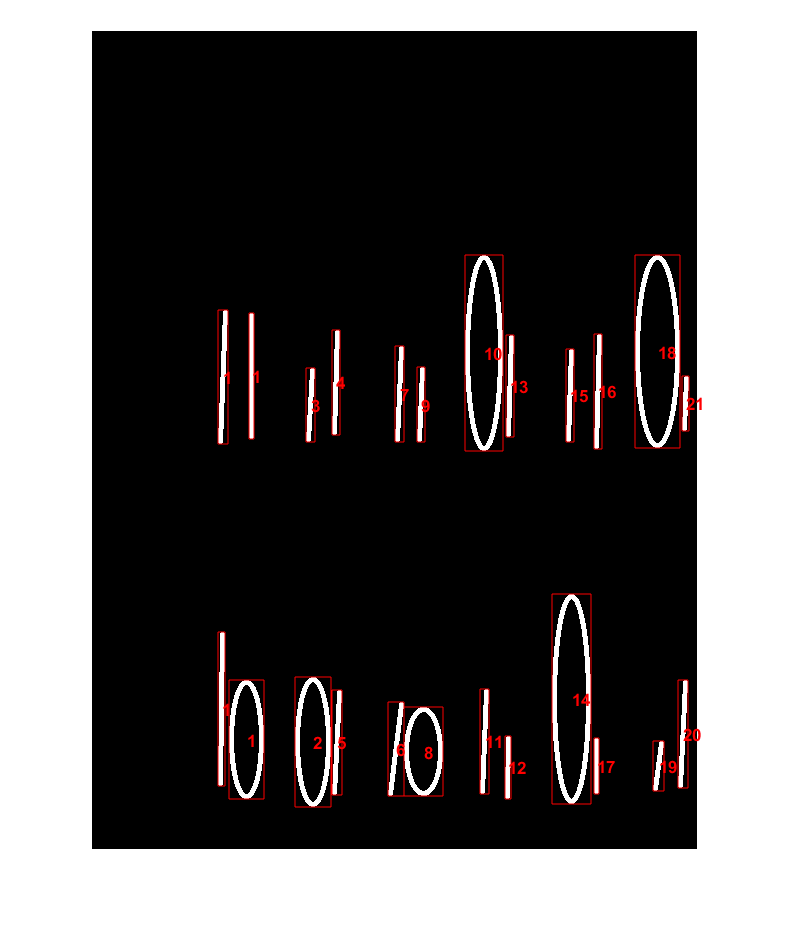



%Initalize array that will hold all questions
questionsArray = zeros(numOfOptions,numOfParameters,numOfQuestions);


%Initialize the question counter and the Question Number
optionNum = 1;
questionNum = 1;

for i=1:numOfBlobs
    % Each region is part of a Question
    if(optionNum > numOfOptions)
        count = 1;
        % Increment Question number every # of options
        questionNum = questionNum +1;
    end
    
    % Get the bounding box for the option
    % Bounding box will be expanded for non-answers
    bb = props(i).BoundingBox;     
    
    % See if it is an answer and then assign a r or g
    % (note: this could also be true of false)
    isAnswer = 0;  
    if(props(i).BoundingBox(3)>30)
        isAnswer = 1;
    end    
   
    %Add parameters to array
    questionsArray(optionNum, 1, questionNum) = bb(1);
    questionsArray(optionNum, 2, questionNum) = bb(2);
    questionsArray(optionNum, 3, questionNum) = bb(3);
    questionsArray(optionNum, 4, questionNum) = bb(4);
    questionsArray(optionNum, 5, questionNum) = isAnswer;
    
    
    % Draw Text and Bounding box
    rectangle('Position',bb,'EdgeColor','r');
    text(props(i).Centroid(1),props(i).Centroid(2),num2str(questionNum),'Color','r',...
       'FontSize',10,'FontWeight','bold');
    
    %Increment option count
    optionNum = optionNum +1;     
   
 end